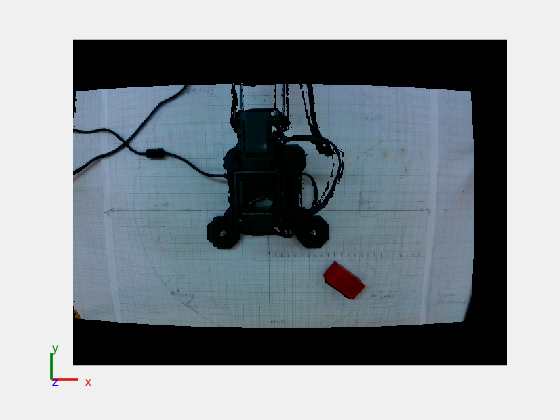

% Starting from default position
sethome(arb);
pause(2);

% Initializing Masks 
[depth_img, imgRGB] = enable_vision();

[redMask, blueMask, greenMask, yellowMask] = createMasks(imgRGB);

%place location
place_x = 19.5;
place_y = 0;

[labeledImage, numObjects] = bwlabel(redMask);
fprintf("Total %d blocks detected", numObjects);

Total 1 blocks detected

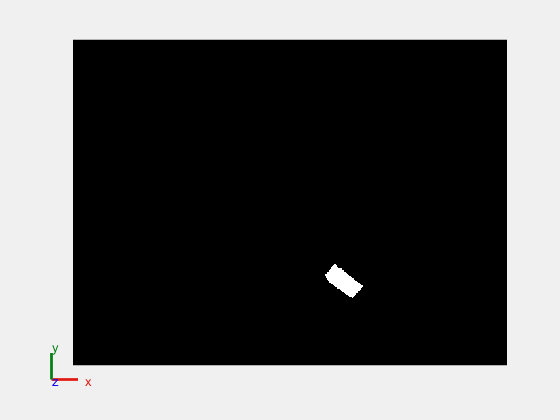

Transformation Matrix (Camera → Block):
    0.7929   -0.6093         0   10.5605
    0.6093    0.7929         0   10.3492
         0         0    1.0000   45.9826
         0         0         0    1.0000

Block position: x=-10.56 cm, y=10.35 cm, z=45.98 cm
Block orientation: -37.5 deg


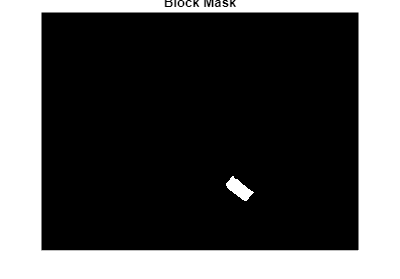

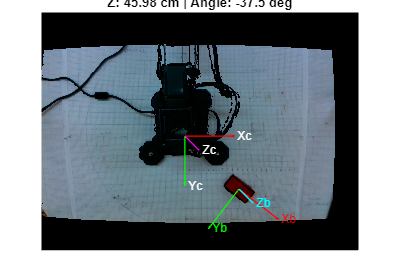

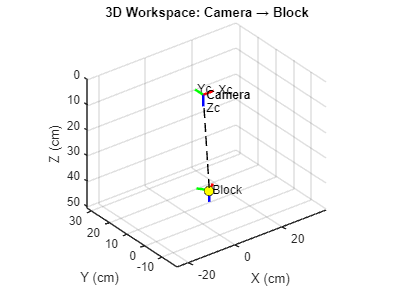

Block is RADIALLY ALIGNED and RECTANGLE.


Pre Grasp Pose



--Candidate 1: [0.7955, -2.2603, 1.5127, -2.3939, 

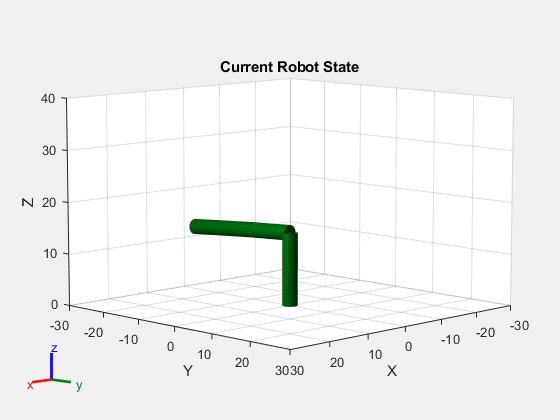

Path is clear! No self-collisions detected.

--Candidate 2: [0.7955, -0.7477, -1.5127, -0.8812, 

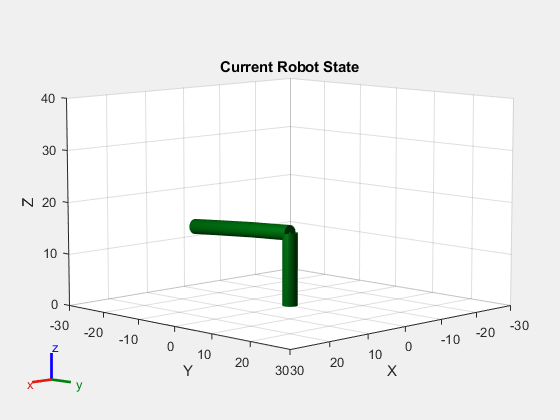

Path is clear! No self-collisions detected.

--Candidate 3: [-2.3461, 0.7477, 1.5127, -5.4019, REJECTED: joint limits violated.

--Candidate 4: [-2.3461, 2.2603, -1.5127, -3.8893, REJECTED: joint limits violated.


Grasp Pose



--Candidate 1: [0.7955, -2.5085, 1.4736, -2.1067, 

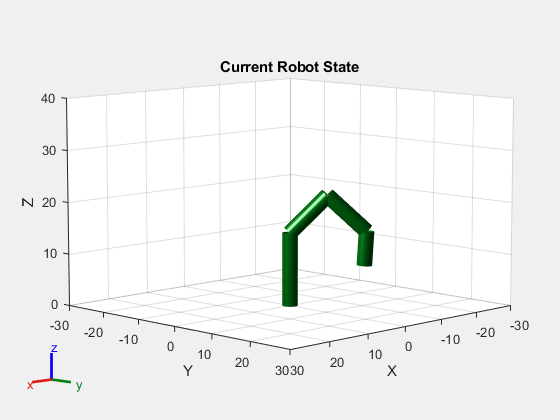

Path is clear! No self-collisions detected.

--Candidate 2: [0.7955, -1.0349, -1.4736, -0.6331, 

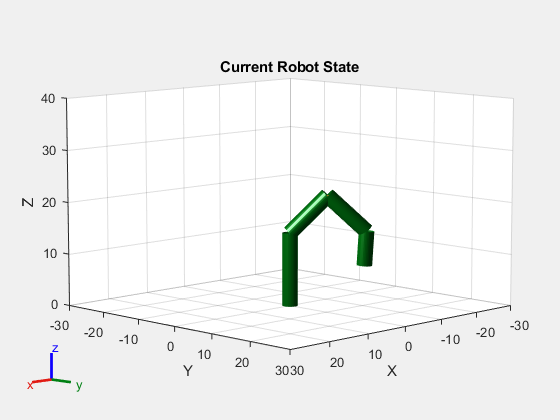

Path is clear! No self-collisions detected.

--Candidate 3: [-2.3461, -5.2483, 1.4736, 0.6331, REJECTED: joint limits violated.

--Candidate 4: [-2.3461, -3.7747, -1.4736, 2.1067, REJECTED: joint limits violated.


Pre Place Pose



--Candidate 1: [-1.5708, -1.4758, 0.3111, -1.9768, 

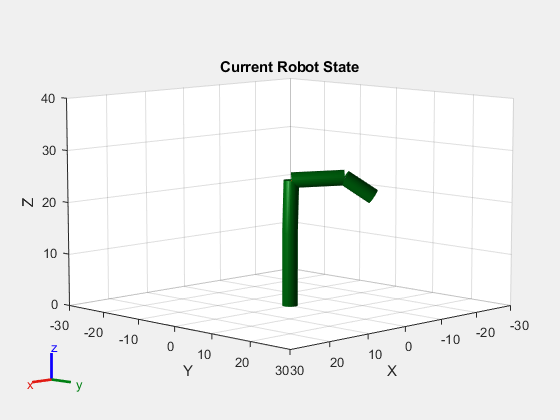

Path is clear! No self-collisions detected.

--Candidate 2: [-1.5708, -1.1648, -0.3111, -1.6657, 

Path is clear! No self-collisions detected.

--Candidate 3: [-4.7124, 1.1648, 0.3111, -4.6174, REJECTED: joint limits violated.

--Candidate 4: [-4.7124, 1.4758, -0.3111, -4.3064, REJECTED: joint limits violated.


Place Pose



--Candidate 1: [-1.5708, -1.9759, 0.5038, -1.6695, 

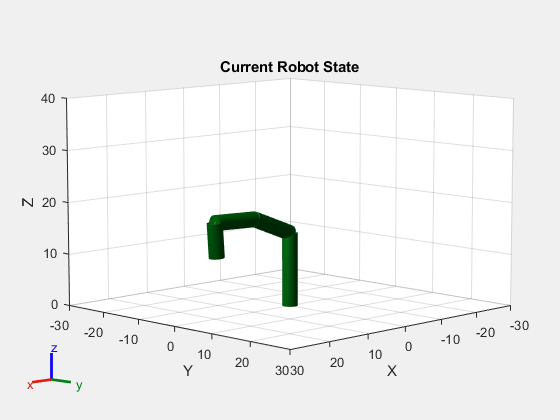

Path is clear! No self-collisions detected.

--Candidate 2: [-1.5708, -1.4721, -0.5038, -1.1657, 

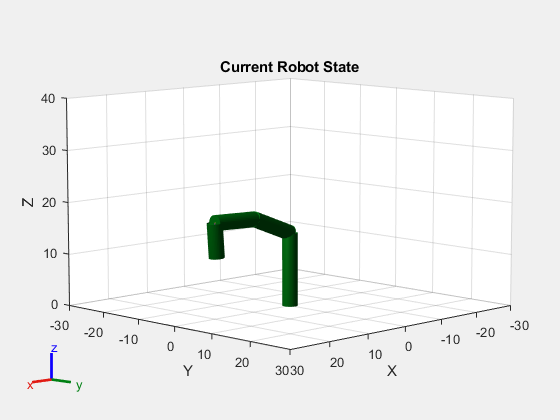

Path is clear! No self-collisions detected.

--Candidate 3: [-4.7124, -4.8111, 0.5038, 1.1657, REJECTED: joint limits violated.

--Candidate 4: [-4.7124, -4.3073, -0.5038, 1.6695, REJECTED: joint limits violated.


Pre Place Pose: Block Placed



--Candidate 1: [-1.5708, -1.8098, 0.5794, -1.9112, 

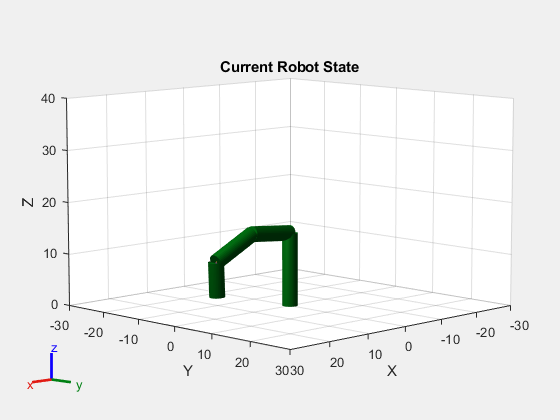

Path is clear! No self-collisions detected.

--Candidate 2: [-1.5708, -1.2304, -0.5794, -1.3318, 

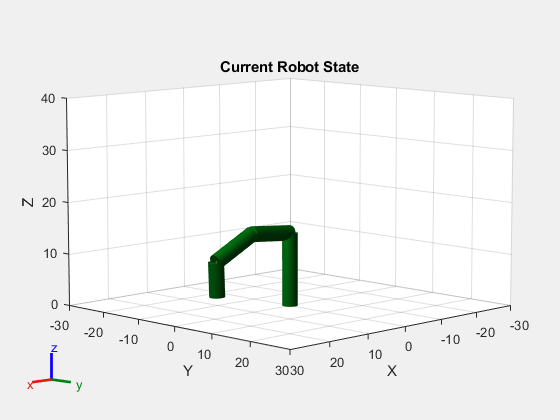

Path is clear! No self-collisions detected.

--Candidate 3: [-4.7124, 1.2304, 0.5794, -4.9514, REJECTED: joint limits violated.

--Candidate 4: [-4.7124, 1.8098, -0.5794, -4.3720, REJECTED: joint limits violated.


x = 18.9242

y = -0.0774

z = 7.2435

phi = -1.6506

for i = 1:numObjects
    objectNumber = i;
    
    objectMask = (labeledImage == objectNumber);
    imshow(objectMask)
    
    % Getting the coordinates of the block with the selected color
    [pick_x, pick_y, pick_z, aligned, shape] = get_position(objectMask, imgRGB, depth_img);
    % pick_x = pick_x - 2;
    if (abs(pick_x) > 22 || abs(pick_y) > 22)
        fprintf("Block out of reach\n");
        continue;
    end

    % checking orientation of the block
    if (~aligned) 
        fprintf("Block %d not aligned\n", i);
        continue; 
    end
    
    if (pick_z > 44)
        pre_z = 8;
        z = 4;
    else 
        pre_z = 10.5;
        z = 6.5;
    end
    
    %finding IK solutions for pick location
    
    %pre-grasp pose
    fprintf("Pre Grasp Pose\n");
    set_optimal(arb, pick_x, pick_y, pre_z);
    if (errorCode ~= 0)
        fprintf("AS NO OPTIMAL IK SOLUTION FOUND, STOPPING THE CYCLE AND GOING TO HOME POSITION\n");
        sethome(arb);
        return;
    end
    pause(4);
    positionJaw(arb, 0); %end-effector completely open
    pause(2);
    
    %grasp pose
    fprintf("Grasp Pose\n");
    set_optimal(arb,pick_x, pick_y, z);
    if (errorCode ~= 0)
        fprintf("AS NO OPTIMAL IK SOLUTION FOUND, STOPPING THE CYCLE AND GOING TO HOME POSITION\n");
        sethome(arb);
        return;
    end
    pause(4);
    positionJaw(arb, 1.15); %end-effector grasping block
    pause(4)
    arb.setpos(2, 0, 50);
    pause(3);  

    % %pre-grasp pose
    % fprintf("Pre Grasp Pose: Block Picked\n");
    % set_optimal(arb, pick_x, pick_y, pre_z);
    % pause(5);

    % pre-place pose
    fprintf("Pre Place Pose\n");
    set_optimal(arb, place_x, place_y, pre_z+4);
    if (errorCode ~= 0)
        fprintf("AS NO OPTIMAL IK SOLUTION FOUND, STOPPING THE CYCLE AND GOING TO HOME POSITION\n");
        sethome(arb);
        return;
    end
    pause(5);
    
    % place pose
    fprintf("Place Pose\n");
    set_optimal(arb, place_x, place_y, z);
    if (errorCode ~= 0)
        fprintf("AS NO OPTIMAL IK SOLUTION FOUND, STOPPING THE CYCLE AND GOING TO HOME POSITION\n");
        sethome(arb);
        return;
    end
    pause(3)
    positionJaw(arb, 0); %end-effector open enough to release the block
    pause(2);

    %verifying accuracy of placement
    [x,y,z,~,~] = pincherFK(arb.getpos());
    pos_error = sqrt((x - place_x)^2 + (y - place_y)^2);
    if pos_error < 0.5
        fprintf('Placement verified. XY error: %.4f cm\n', pos_error);
        success = true;
    else
        fprintf('WARNING: Placement error %.4f cm exceeds tolerance %.4f cm\n', ...
            pos_error, 0.5);
        success = false;
    end
    
    % pre-place pose
    fprintf("Pre Place Pose: Block Placed\n");
    set_optimal(arb, place_x, place_y, pre_z);
    if (errorCode ~= 0)
        fprintf("AS NO OPTIMAL IK SOLUTION FOUND, STOPPING THE CYCLE AND GOING TO HOME POSITION\n");
        sethome(arb);
        return;
    end
    pause(3) 
    
    %going back to home position
    sethome(arb);
    pause(5);
end

fprintf("All cubes placed\n")

All cubes placed


sethome(arb);